# **Adjustment for Non_Linear GH  **

%Unknown X, Residual
addpath Template_data/
addpath Function/
clearvars


**1. Input Data(Copy here only)**

Elist=["Free_=|Ext('13fix2.txt','y:x','PTYX')|"
    "Free_data=[Ext('13fix2.txt','y:x','PTYX');]"
    "L_=|Ext('13dir2.txt','DIR','DIR')|Ext('13dis2.txt','DIS','DIS')|"
    "L_data=[u2u('1gon')*Ext('13dir2.txt','DIR','DIR');Ext('13dis2.txt','DIS','DIS')]"
    "X_=|Ext('13new2.txt','y:x','PTYX')|Ext('13dir2.txt','w','W')|"
    "X_data=[Ext('13new2.txt','y:x','PTYX');Ext('13dir2.txt','w','W')]"];
AnalyzeEList(Elist)
[L_i,X_i]=findDIR();

[Var_ind,Var_name]=findVar();
S_L=expand_V(ones(size(L_)),Var_ind,u2u("1mgon 1cm"));  

F_ = [DIR-Get_Funlist(DIR,{"x","y","w"},"DIR");
    DIS-Get_Funlist(DIS,{"x","y"},"DIS");
    ]; 




**2. Setup your Output and Threshold**

VCE_CONFIG=false; %Variance Component Estimation
epsilon = 10^-6; %Convergence
delta = 1e-6; %Convergence
L_Config=false;  %display output for L
SLL_Config=false; %display output for S
Func_Config=true; %display output for Function Model
Cons_Config=true; %display output for Constrint
A_Config=false; %display output for Design Matrix
Obs_Config=true; %display output for Observation


## **1. Gaussian **Helmert  Model

**Preprocess**


checkConfig();

The angle in L_. 


ans = table
        Var1     
    _____________

    [1×18 string]


... will be generate F_m
... converted to gon 
The angle in X_. 


ans = table
        Var1    
    ____________

    [1×7 string]


... will be converted to gon 


if ~isempty(L_i)
    if sum(contains(string(L_(L_i)+F_(L_i)),string(L_(L_i))))>0
        F_m=F_;  
        F_m(L_i)=L_(L_i)-mod(-(F_(L_i)-L_(L_i)),2*pi);  %L+Fuc
    else
        F_m=F_;
        F_m(L_i)=-L_(L_i)+mod(F_(L_i)+L_(L_i),2*pi);  %-L+Fuc
    end
else
    F_m=F_;
end

%Number of observations
no_n =  length(F_);
%Number of unknowns
no_u = length(X_);
%Redundancy
redundancy = no_n-no_u;

**Function and Observation**

if ~exist("dash")
    dash=[0];
end
L_dash_=L_+dash;
F_=F_+dash;   
F_m=F_m+dash;

if L_Config
    disp("=========================")
    disp("1. Observation Vector (Observation)") 
    disp("=========================")
    L_==L_data+dash    %Show here
end

**Stochastic Model**


sigma_0 =1;
if ~exist("S_LL")
    S_LL = diag(S_L.^2);     %Show here
end
if ~exist("S_L")
    S_L = diag(S_LL);       %Show here
end

Q_LL = 1/sigma_0^2*S_LL;
P_LL = inv(Q_LL); 
 
%Theoretical reference standard deviation
sigma_0 = 1;     %a priori

%Cofactor matrix of the observations
Q_LL = inv(P_LL);
if SLL_Config
    disp("=========================")
    disp("2. Stochastic Model (SLL/P)") 
    disp("=========================")
    diag(L_.^2)  %Show here
end

**Constraint**

if exist("cons_info","var")

    B_=cons_info{1};
    if ~isempty(cons_info{2})
        FB_=cons_info{2};
    end
       %Show Here
    no_b=size(B_);
    no_b=no_b(1);
    redundancy = no_n-no_u+no_b;
end
if Cons_Config 
    if exist("cons_info","var")
        disp("=========================")
        disp("3.Constraint Model (Constraint Model)") 
        disp("=========================")
        display(cons_info{4})
        Cons_model=FB_==LB_data    %Show Here
        B_
    end
end

**Function Model**

if Func_Config
    disp("=========================")
    disp("3.Function Model (Redundancy, Function)") 
    disp("=========================")
    0==F_   %Show Here
    redundancy  %Show Here
end

3.Function Model (Redundancy, Function)


redundancy =     21


**Observation Equation**

 
% Observation Equation

syms V_ [length(L_),1];
Ndeal(L_,V_+L_)
psi_=eval(F_);
psi_m=eval(F_m);
J1_=jacobian(psi_,X_);  %Show Here
J2_=jacobian(psi_,L_);

if A_Config
    disp("=========================")
    disp("4.Observation Equation(Design Matrix, Objective)") 
    disp("=========================")
    J1_
    J2_

end
if Obs_Config
    disp("=========================")
    disp("5.Observation Equation(Objective)") 
    disp("=========================")
    disp("O=vTPv--->min")   %Show Here
    psi_==0
end

5.Observation Equation(Objective)


O=vTPv--->min


**Input Data**

% 6.Measurement L
Ndeal(L_, L_data)
% 7.Free Error X
Ndeal(Free_, Free_data)
% 8.Initial values for the unknowns
Ndeal(X_, X_data)
% 8.Initial values for the V
Ndeal(V_, zeros(size(V_)))

if exist("LB_","var"),Ndeal(LB_, LB_data); end
if exist("X_O","var"),Ndeal(X_O, X_data); end 

## **2. Adjustment**

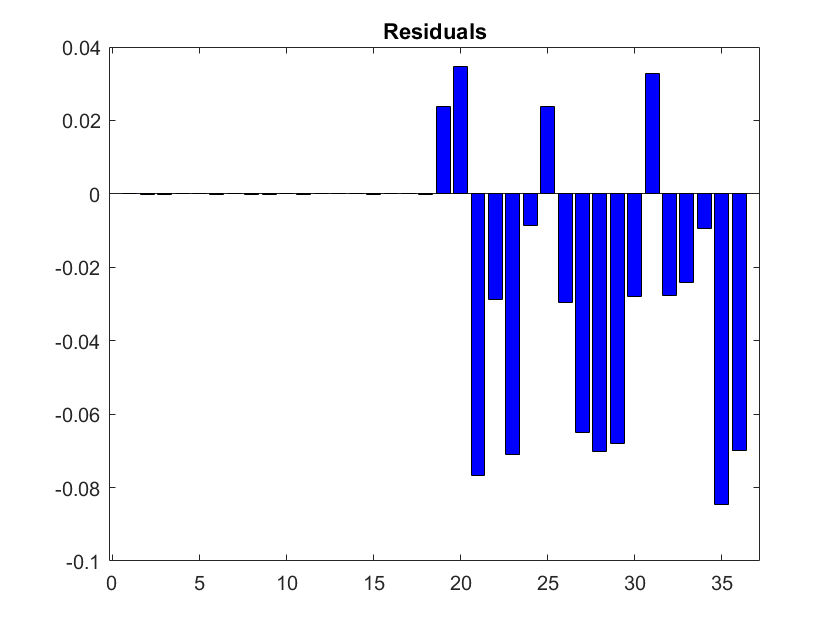

 
L_0=eval(L_);
V_0=eval(V_);
L_dash_0=eval(L_dash_);
X_0=eval(X_);
L_dash_hat=eval(L_dash_);
V_hat=eval(V_);
%break-off conditions
languMultiplyer=0;
iteration = 0;
max_psi=10^Inf;
syms thx
safe=thx;
thx=0;
checkVCE=true;
vce_iter=0;

if VCE_CONFIG==true
% initial values
    a_all=expand_V(zeros(size(L_)),Var_ind,1*ones(length(Var_ind),1));
    s_o_all=expand_V(zeros(size(L_)),Var_ind,10^10*ones(length(Var_ind),1));
end
%VCE
while checkVCE
    vce_iter=vce_iter+1;
    
    if VCE_CONFIG==true
        %Iteration 1
        checkVCE=sum(abs(s_o_all-1)>10^-4)~=0;
        %VC Matrix of the observations
        C_LL_all=diag(a_all.^2.*S_L.^2);
        %Cofactor matrix of the observations
        Q_LL=1/sigma_0^2*C_LL_all;
        P_LL = inv(Q_LL); 
    else
        checkVCE=0;
    end
    
    %break-off conditions    
    max_psi=10^Inf;
    while  max_psi>epsilon || max(abs(eval(F_m)))>delta
        Ndeal(L_,L_0); 
        iteration=iteration+1;
        
        J1_evl=eval(J1_+safe);
        J2_evl=eval(J2_+safe);
        psi_evl=eval(psi_m);
 
        c_evl=0;
        w1_evl=-J2_evl*V_hat+psi_evl-c_evl;
                
        
        if exist("cons_info","var")
            if exist("cons_info") 
                FB_evl=eval(FB_);
                B_evl=eval(B_+safe);  
                w2_evl=FB_evl-eval(LB_data+safe);
                n_ext = [J1_evl'*inv(J2_evl*Q_LL*J2_evl')*w1_evl;-w2_evl];
            else
                error("flag is not right")
        
            end
            
            N_ext = [-J1_evl'*inv(J2_evl*Q_LL*J2_evl')*J1_evl B_evl'; B_evl 0];
            Q_xx_ext = inv(N_ext);
            %n_ext = [n;zeros(no_b,1)];
            
            %Inversion of normal matrix / Cofactor matrix of the unknowns
            
            Q_XX = Q_xx_ext(1:no_u,1:no_u);    
            %Solution of normal equation
            X_smallhat=Q_xx_ext*n_ext;  
            k1 = inv(J2_evl*Q_LL*J2_evl')*(-J1_evl*X_smallhat(1:end-1)-w1_evl);
            k2=X_smallhat(end);
            V_hat = Q_LL*J2_evl'*k1;
            Ndeal(V_,V_hat);
            Ndeal(X_,X_smallhat(1:no_u)+eval(X_));
            
 
        else
            %Vector of right hand side of normal equations
            
            N = J2_evl*Q_LL*J2_evl'; 
            n_ext =  [-w1_evl ; zeros(no_u,1)];
            N_ext=[N J1_evl; J1_evl' zeros(no_u,no_u)]; 
            Q_xx_ext = inv(N_ext);
            X_smallhat=Q_xx_ext*n_ext;  
            %ka=X_smallhat(1:no_n);
            ka= inv(N)*(-w1_evl);
            V_hat=Q_LL*J2_evl'*ka;
            Ndeal(V_,V_hat);
            Ndeal(X_,X_smallhat(end-no_u+1:end)+eval(X_));
        end
        

        max_psi=max(abs(psi_evl));
        V_hat_rad=V_hat;
        % Update v

        L_dash_hat = L_dash_0+V_hat;
        L_hat=L_0+V_hat;
        X_hat=eval(X_);
        Ndeal(X_O,X_hat);
        %Objective function
        vTPv = V_hat'*P_LL*V_hat;
        languMultiplyer=languMultiplyer+X_smallhat(no_u+1:length(X_smallhat));
        if iteration > 100
            error("Wrong")
        elseif vce_iter > 20
            error("Wrong VCE")
        end
        Ndeal(L_,L_0+V_hat);
    end
    
    %Empirical reference standard deviation
    s_0 = sqrt(vTPv/(redundancy));     %a posteriori
    
    if exist("cons_info","var")
        %VC matrix of adjusted unknowns
        S_XX_hat = -s_0^2*Q_xx_ext(1:no_u,1:no_u);
        %Cofactor matrix of adjusted observations
        Q_vv = Q_LL*J2_evl'*inv(J2_evl*Q_LL*J2_evl')*J2_evl*Q_LL;
    else
        %VC matrix of adjusted unknowns
        S_XX_hat = -s_0^2*Q_xx_ext(end-no_u+1:end,end-no_u+1:end);
        %Cofactor matrix of the residuals HERE
        %Q_vv = Q_LL*J2_evl'*inv(J2_evl*Q_LL*J2_evl')*J2_evl*Q_LL;
        Q_vv = Q_LL*J2_evl'*Q_xx_ext(1:no_n,1:no_n)*J2_evl*Q_LL;
    end
    Q_LL_hat = Q_LL-Q_vv;
    S_LL_hat = s_0^2*Q_LL_hat;
    S_vv = s_0^2*Q_vv; 
    S_v=sqrt(diag(S_vv));
    S_X=sqrt(diag(S_XX_hat));
    S_L_hat=sqrt(diag(S_LL_hat));

    %Check VCE 
    Q_vvP = Q_vv*P_LL;
    if VCE_CONFIG==true       %~exist("Var_ind")
        %[Var_ind,Var_name]=findVar();

        for i =1:length(Var_ind)
            P_dist=P_LL(Var_ind{i},Var_ind{i});
            Q_vvP_dist=Q_vvP(Var_ind{i},Var_ind{i});
            %Sub-vectors of residuals
            v_dist = V_hat_rad(Var_ind{i},1);          %sub-vector of v
            %Compute trace for sub-matrices Q_vvP_dist and Q_vvP_dir
            r_dist = trace(Q_vvP_dist);
            s_o_dist(i,1) =sqrt((v_dist'*P_dist*v_dist)/r_dist);
        end
 
        s_o_all=expand_V(zeros(size(L_)),Var_ind,s_o_dist);
        a_all=a_all.*s_o_all;
    end

end

%plotxyc(X,L_dash,eval(F_))
figure
bar(V_hat,"b")
title("Residuals")


%Final check
if max(abs(eval(F_m)))<delta
    disp("Good")
else
    disp("Wrong")
end

Good


**Restore the centroid Back (if have)**


if exist("list_info") && length(list_info)==3
            [X_hat,useless]=normalizeX_(X_hat,"inverse",list_info);
            [X_0,useless]=normalizeX_(X_0,"inverse",list_info);
            Ndeal(X_,X_hat);
            disp("Xhat=Xhat+centroid")
            
end
if exist("rescale_L1") 
            [L_hat,useless]=normalizeL_(L_hat,"inverse",rescale_L1);
            [L_0,useless]=normalizeL_(L_0,"inverse",rescale_L1);
            close1=eval(F_);
            Ndeal(L_,L_hat);
            Ndeal(X_,X_sym);
            %Detect
            X_lr_index=[];
            X_nl_index=[];
            for i = 1: length(X_sym)
                if sum(contains(string(eval(J1_+safe)),string(X_sym(i))))==0
                    X_lr_index=[X_lr_index,i];
                else
                    X_nl_index=[X_nl_index,i];
                end
            end
            X_lr=X_(X_lr_index);
            Ndeal(X_(X_nl_index),X_hat(X_nl_index));
            eqn=eval(F_+safe)==close1;
            uniqlist=[];
            for i=1:length(X_lr)
               F_Contain_X{i}=find(contains(string(eval(F_+safe)),string(X_lr(i))));
               LenFCX(i)=length(F_Contain_X{i});
            end
            [out,order_idx] = sort(LenFCX);
            for i=order_idx
                eqnlisttemp=F_Contain_X{i};
                for j=1:LenFCX(i)
                    if ~ismember(eqnlisttemp(j),uniqlist)
                       uniqlist=[uniqlist eqnlisttemp(j)]; 
                       break
                    end
                end
            end
            sol = struct2cell(solve(eqn(uniqlist), X_lr));
            X_hatnew=X_hat;
            for i=1:length(X_lr_index)
                X_hatnew(X_lr_index(i))=eval(sol{i}+safe);
            end
            disp("L_data=L_data+centroid")
            disp("Updating X_hat by solving Linear equation") 
            Unknown=arrayfun(@(x) sprintf("%s",x),X_);
            table(Unknown,X_hat,X_hatnew)
            X_hat=X_hatnew;
end
if exist("cons_info",'var')
    rank_deficient=size(J2_evl*Q_LL*J2_evl');
    rank_deficient=rank_deficient(1)-rank(J2_evl*Q_LL*J2_evl')
    LB_data-eval(FB_)
end

**Get X, L, and residual.**

%Conversion
if exist("X_i",'var')
    X_hat(X_i)=mod(X_hat(X_i)*200/pi,400);
    S_X(X_i)=S_X(X_i)*200/pi;
end    
if exist("L_i",'var')
    L_0(L_i)=L_0(L_i)*200/pi;
    L_dash_hat(L_i)=mod(L_dash_hat(L_i)*200/pi,400);
    L_hat(L_i)=mod(L_hat(L_i)*200/pi,400);
    S_L_hat(L_i)=S_L_hat(L_i)*200/pi;
    V_hat(L_i)=V_hat(L_i)*200/pi;
    S_v(L_i)=S_v(L_i)*200/pi;
end

disp("=========================")

disp("6.Get Result and S_xx") 

6.Get Result and S_xx


disp("=========================")

format long


disp("Get Unknown X_hat, S_x:") 

Get Unknown X_hat, S_x:


Unknown=arrayfun(@(x) sprintf("%s",x),X_);
table(Unknown,X_0,X_hat,S_X)

ans = 15×4 table
    Unknown       X_0            X_hat                  S_X        
    _______    _________    ________________    ___________________

    "y100"     4590159.8    4590159.82346832     0.0232649800858116
    "y101"     4589800.1     4589800.1336909     0.0396468395499771
    "y102"     4590163.2    4590163.22359582     0.0250768967549978
    "y103"     4589956.9    4589956.95734631     0.0237915396629105
    "x100"     5820727.3    5820727.41366987     0.0160922824643821
    "x101"     5820857.9    5820857.98605946     0.0474611389110593
    "x102"     5820848.7    5820848.80441443     0.0159755438465634
    "x103"     5820700.4    5820700.49441259     0.0229076260298337
    "w1000"            0    398.678365155439    0.00713359906883875
    "w2000"            0    398.368289888786      0.016877250923084
    "w3000"            0    39


disp("Get Updated L_hat, S_l:") 

Get Updated L_hat, S_l:


Measurment=arrayfun(@(x) sprintf("%s",x),L_);
table(Measurment,L_0,L_hat,L_dash_hat,S_L_hat,["V_"+(1:length(V_hat))'],V_hat,S_v)

ans = 36×8 table
     Measurment        L_0            L_hat             L_dash_hat             S_L_hat           Var6            V_hat                    S_v        
    _____________    ________    ________________    ________________    ___________________    ______    ____________________    ___________________

    "DIR1000_100"     269.698    269.705504086418    269.705504086418    0.00697558407372545    "V_1"      0.00750408641790112    0.00528945214881729
    "DIR1000_102"    310.4634      310.4558959138      310.4558959138    0.00697558407372545    "V_2"     -0.00750408620015328    0.00528945214881729
    "DIR2000_103"    207.9866    207.983616831135    207.983616831135    0.00788654293504371    "V_3"     -0.0

**Get VCE Result**

if VCE_CONFIG==false       %~exist("Var_ind")
    [Var_ind,Var_name]=findVar();

    for i =1:length(Var_ind)
        P_dist=P_LL(Var_ind{i},Var_ind{i});
        Q_vvP_dist=Q_vvP(Var_ind{i},Var_ind{i});
        %Sub-vectors of residuals
        v_dist = V_hat_rad(Var_ind{i},1);          %sub-vector of v
        %Compute trace for sub-matrices Q_vvP_dist and Q_vvP_dir
        r_dist = trace(Q_vvP_dist);
        s_o_dist(i,1) =sqrt((v_dist'*P_dist*v_dist)/r_dist);
    end

    s_o_all=expand_V(zeros(size(L_)),Var_ind,s_o_dist);
    a_all=expand_V(zeros(size(L_)),Var_ind,1*ones(length(Var_ind),1));
    a_all=a_all.*s_o_all;
    
end
    

try
    disp("Variance Component") 
    a_all_dist=unique(a_all);
    table(Var_name,s_o_dist,a_all_dist) 
catch

    table(Measurment,s_o_all,a_all) 
end

Variance Component


ans = 2×3 table
    Var_name        s_o_dist           a_all_dist   
    ________    ________________    ________________

     "DIR"      15.4931260476949     5.2325388628912
     "DIS"       5.2325388628912    15.4931260476949


## **3. Quality Assessment**

**Global test**

disp("Global test") 

Global test


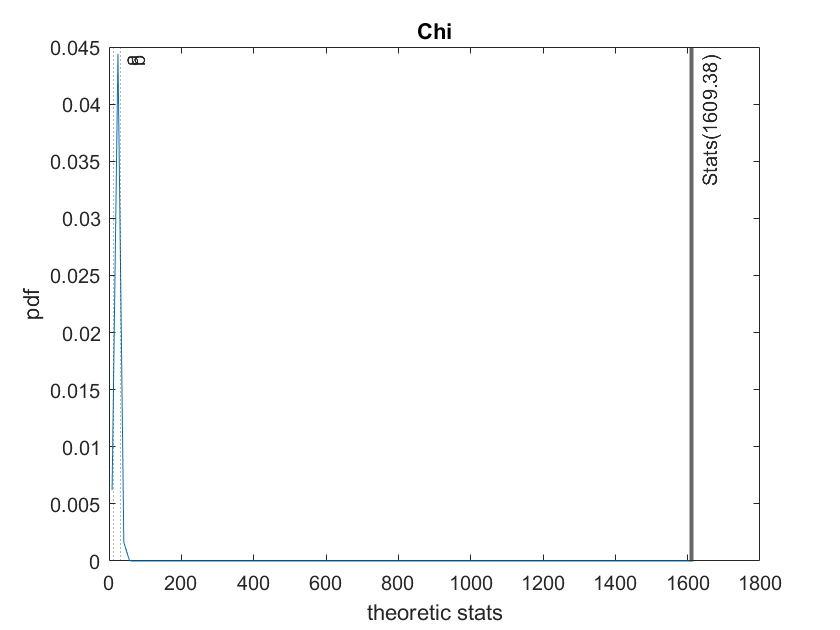

Test Statistic: 1609.38 ,Critical value=[11.59,32.67]
1,Reject the null hypothesis H0: Same
1,Reject HC: Significant smaller with S=95.00%
2.Choose hypothesis HA: Significant Bigger with S=95.00%
2.Choose hypothesis HB: Significant difference with S=90.00%


confidence_tool=confidence_tool();
stats=confidence_tool.statistic_test_chi(0.95, sigma_0, s_0, redundancy);




disp("Internal and external reliability parameters") 

Internal and external reliability parameters



%Check 3σ rule
mat=S_L;  

%Compute EV
r_i=diag(Q_vv*P_LL);
EV=r_i*100;

% NV
sigma_v=sigma_0*sqrt(diag(Q_vv));
NV=abs(V_hat_rad)./sigma_v;


for j=1:size(mat)
    % 3 sigma update
    if V_hat_rad(j)>(3*mat(j)) || V_hat_rad(j)<(-3*mat(j))
        sigma3_rule(j,1)="exceed 3sigma";
    else
        sigma3_rule(j,1)="Good";
    end
    % EV update
    if EV(j)<1
        EV_comment(j,1)="not controlled";
    elseif EV(j)<10
        EV_comment(j,1)="poorly controlled";
    elseif EV(j)<30
        EV_comment(j,1)="sufficiently controlled";
    elseif EV(j)<70
        EV_comment(j,1)="good controlled";   
    else
        EV_comment(j,1)="Excellent";   
    end
    
    % NV
    if NV(j)<2.5
        NV_comment(j,1)="no blunder";
    elseif NV(j)<4
        NV_comment(j,1)="blunder possible";
        blunder=true;
    else
        NV_comment(j,1)="blunder highly";   
        blunder=true;
    end  
    
end



% Potential magnitude of a blunder
GF=-V_hat_rad./r_i;
 
% Lower boundary value for blunders
GRZW=ones(size(V_hat_rad)); % help matlab with memory by making a empty matrix
for i=1:length(GRZW)
    GRZW(i,1)=sigma_0*4.13/sqrt(r_i(i,1)*P_LL(i,i));
end



GF(L_i,1) = GF(L_i,1)*200/pi;

GRZW(L_i,1)=GRZW(L_i,1)*200/pi;   % we change those measurments that were  amgles


P_diag=diag(P_LL);
dd=ones(size(r_i));
rw=zeros(size(r_i));


for i=1:length(L_i)
    target_name=Measurment(L_i(i));
    target_name=regexp(target_name,'\d*\.?\d*','match');
    num_1=target_name{1};
    num_2=target_name{2};
    
    %get dis
    if exist(["DIS"+num_1+"_"+num_2])
        dd(L_i(i))=eval(["DIS"+num_1+"_"+num_2]);
    elseif exist(["DIS"+num_2+"_"+num_1])
        dd(L_i(i))=eval(["DIS"+num_2+"_"+num_1]);
    else
        warning("there is no "+["DIS"+num_2+"_"+num_1])
        dd(L_i(i))=1;
    end
    Psum_i=find(contains(Measurment,["DIR"+num_1+"_"]));
    PSum=sum(P_diag(Psum_i));
    rw(L_i(i))=P_diag(L_i(i))/PSum;
end

r_i_w=1-r_i;
r_i_w=(r_i_w-rw).*dd;

EP=r_i_w.*GF;
EGK=r_i_w.*GRZW;

[mValue , vIndex] =max(V_hat_rad);
blunderstr=Measurment(vIndex);


**Interior and exterior Check**

table(Measurment,V_hat_rad,S_L_hat,sigma3_rule,EV,EV_comment,GF,GRZW,NV,NV_comment,EP,EGK)

ans = 36×12 table
     Measurment            V_hat_rad                S_L_hat          sigma3_rule           EV                  EV_comment                     GF                    GRZW                   NV               NV_comment               EP                   EGK       
    _____________    _____________________    ___________________    ___________    ________________    _________________________    ____________________    ___________________    _________________    ________________    __________________    _________________

    "DIR1000_100"     0.000117873913811906    0.006

**Lagrange Multiplier**

if exist("cons_info","var")
try 
disp("Show Lagrange Multiplier")
languMultiplyer
catch
disp("No Lagrange Multiplier")
end  
end

**Blunder Detector**


if exist("blunder")
    disp("========================================================================")
    disp("========================================================================")
    disp("There exist blunder point, pls remove the point: "+blunderstr)
    disp("The residual is : "+num2str(mValue))
    disp("========================================================================")
    disp("========================================================================")

end

There exist blunder point, pls remove the point: DIS1000_102


The residual is : 0.034667
